## Aperture (apodization)

The shape of the aperture can have a significant impact on the image.  We have been assuming that the aperture is circular, and in this example we will create images with different aperture shapes.

ieInit % Start ISETCam

SceneFirst, create a high dynamic range scene.  This will reveal the details of the point spread clearly.

scene = sceneCreate('hdr image',...
    'dynamic range',5,...
    'patch shape','circle','npatches',5,'patch size',10);

Now create an oi, and notice that we can ask for the wavefront structure to be returned at the time of creation.

[oi,wvf] = oiCreate('wvf');

This sets the sample density of the aperture image. We use a high sampling density to show the details clearly.

wvf = wvfSet(wvf,'npixels',512);

## Apertures

We will create apertures with several different polygon sides, or with a circular shape.

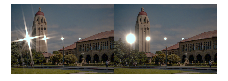

% nsides = [4 6 8 0];   % 0 means a circular shape.
nsides = [4 0];   % 0 means a circular shape.
img = cell(numel(nsides),1);
sensor = [];

for ii = 1:numel(nsides)
    [aperture, params] = wvfAperture(wvf,'nsides',nsides(ii),...
        'dot mean',10, 'dot sd',5, 'dot opacity',0.5,'dot radius',5,...
        'line mean',10, 'line sd', 5, 'line opacity',0.5,'linewidth',2);

    oi = oiSet(oi,'fnumber',1.5);
    oi = oiSet(oi,'focal length',4.38e-3,'m');

    oi = oiCompute(oi, scene,'crop',true,'pixel size',3e-6,'aperture',aperture);

    oi = oiAdjustIlluminance(oi, 100);
    
    % We visualize the result in the image processor window. This is just
    % to show off - I could have stopped at the oi. But I want you to know
    % that we do simulate sensors and image processing.
    if isempty(sensor)
        % First time through, create a sensor using this function.  We
        % could have created one of many different sensors, but this one is
        % a simple, default that matches the spatial resolution of the oi.
        [ip,sensor] = piRadiance2RGB(oi,'etime',1/10);
    else
        % Second and other times, use the sensor we created
        sensor = sensorCompute(sensor,oi);
        ip = ipCompute(ip,sensor);
    end

    % Save the rendered image.
    img{ii} = ipGet(ip,'srgb');    
end

montage(img,'Size',[1, numel(nsides)]);


%{
fname = fullfile(fiseRootPath,'chapters','images','optics','06-geometric','pinhole-shape-1.png');
exportgraphics(gcf,fname);
%}

## Rectangular aperture

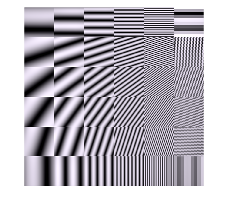

% scene = sceneCreate('sweepfrequency',512,16)
parms.angles = linspace(0,pi/2,6); parms.freqs =  [1,2,4,8,16,32];
parms.blockSize = 128; parms.contrast = .8;
scene = sceneCreate('frequency orientation',parms);
scene = sceneSet(scene,'fov',2);
sceneWindow(scene);

% sceneCreate('sweep frequency',imageSize,maxFrequency);
wvf = wvfCreate;
wvf = wvfSet(wvf,'npixels',512);
aperture = wvfAperture(wvf,'shape',...
    'rectangle','aspect ratio',[2 1], ...
    'dot mean',0,'dot sd',0,...
    'line mean',0,'line sd',0);

oi = oiCompute(oi, scene,'crop',true,'pixel size',1e-6,'aperture',aperture);
oi = oiAdjustIlluminance(oi, 100);
oiWindow(oi);

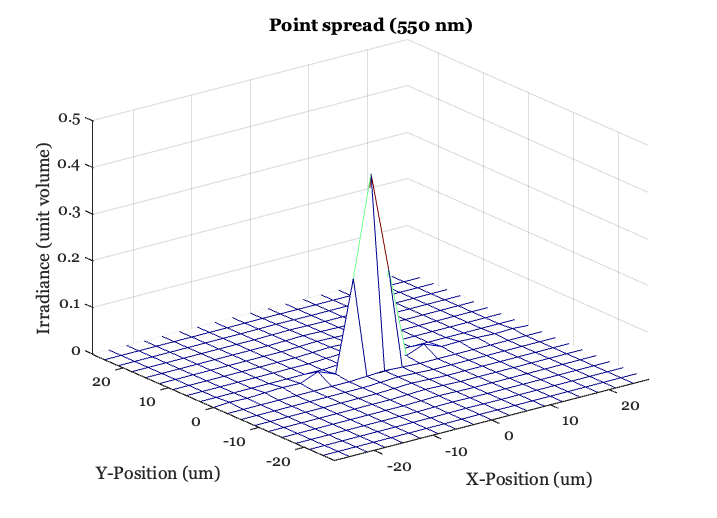

oiPlot(oi,'psf');